%%%%%%%%%%%%%%%%%%%%%%%           ！！！Focus lens generate automatic script！！！         %%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%            ！！！The fruit is stored in the x vector          %%%%%%%%%%%%%%%%

L = 2E-2;%%%%m;                  ！！！Lens radius！！！
a = 20E-6;%%%%m;                 ！！！slit width
pixel_n = L/a/2;
pixel_n=round(pixel_n);
void = 4;  %                     ！！！Number of slits corresponding to the central constant open area (half)！！！

%%%%%%%%%%%%%%%%%%%%%%%%%%%%constraint condition%%%%%%%%%%%%%%%%%%%%%%%%%
count1=ones(1,pixel_n);
count2=-ones(1,pixel_n);
d1=ones(1,pixel_n);
d2=ones(1,pixel_n-1);
count3=diag(d1)+diag(d2,1);
count_b1=[250;-50];                 %%%%%%%%
count_b2=1*ones(pixel_n,1);
count_b2(pixel_n-void:pixel_n,1)=2;              
count=[count1;count2;count3];
count_b=[count_b1;count_b2];

intcon=(1:pixel_n);
lb=zeros(1,pixel_n);
lb(1,pixel_n-void:pixel_n)=1;
ub=ones(1,pixel_n);

nvars=pixel_n;
Aineq=count;
bineq=count_b;
PopulationSize_Data=100;
MaxGenerations_Data=300;

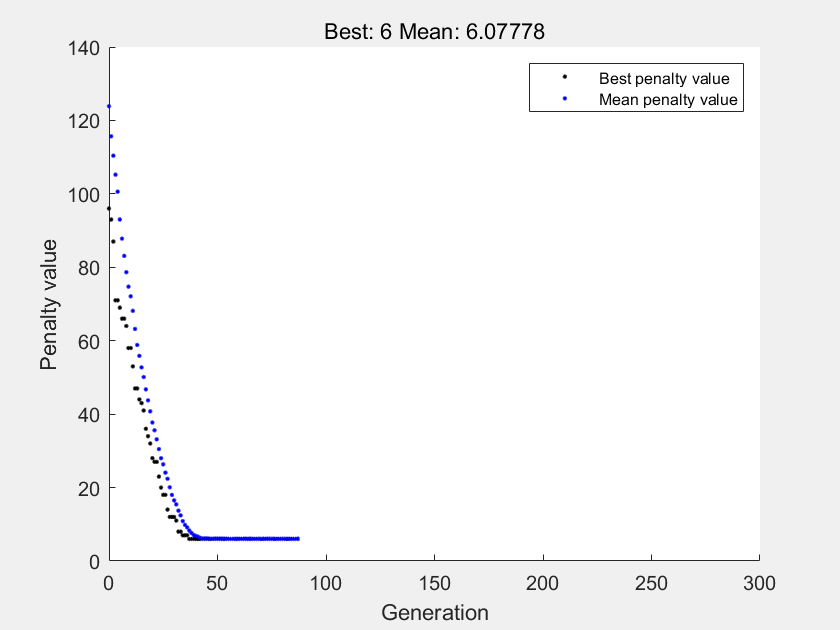

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
but constraints are not satisfied.


options = optimoptions("ga",'PopulationSize', PopulationSize_Data,'MaxGenerations', MaxGenerations_Data,'PlotFcn', @gaplotbestf);
%% Modify options setting
%options = optimoptions(options,'PopulationSize', PopulationSize_Data);
%options = optimoptions(options,'MaxGenerations', MaxGenerations_Data);
%options = optimoptions(options,'InitialPopulationMatrix', InitialPopulationMatrix_Data);
%options = optimoptions(options,'Display', 'final');
%options = optimoptions(options,'PlotFcn', { @gaplotbestf });
rng default;
[x,fval,exitflag,output,population,score] = ga(@fitfun_focal_S,nvars,Aineq,bineq,[],[],lb,ub,[],intcon,options);